% newData = readtable('CNV_Input.csv','ReadRowNames',true,'PreserveVariableNames',true);
% save('newData.mat', 'newData');

%newData=CNVlog2transout(2:end,2:end);
%save('newData.mat', 'newData');
cd ./Input_Data/
load('newData.mat');

[d,t1] = xlsread('clinical_labels.xlsx');
response = categorical(d(:,6));
%newData.class = response;
%feature_table = newData;

CNVdatawithlabels = (table2array(newData))';
[Mask, FData] = genevarfilter(CNVdatawithlabels, 'Percentile', 50);
CNVdatawithlabels_F = CNVdatawithlabels(Mask,:);

[Mask_ENTROPY, FData_ENTROPY] = geneentropyfilter(CNVdatawithlabels_F, 'Percentile', 60);
CNVdatawithlabels_Final= FData_ENTROPY;

CNVdatawithlabels_Final_T=CNVdatawithlabels_Final';
cv = cvpartition(size(CNVdatawithlabels_Final_T,1),'HoldOut',0.2);
idx = cv.test;
dataTrain = CNVdatawithlabels_Final_T(~idx,:);
dataTest  = CNVdatawithlabels_Final_T(idx,:);
clinFeatures= d(:,[1:5])

clinFeatures =     42     1    49     2     3
    65     0     9     1     3
    49     0    81     2     3
    45     0   147     2     2
    69     1   136     3     3
    48     0   179     2     3
    73     1    52     1     2
    75     0   175     4     2
    54     1   182     2     3
    58     1   203     7     3


clinicaldata_Train = (clinFeatures(~idx,:))';
clinicaldata_Test = clinFeatures(idx,:);

DataTrain=table(dataTrain,clinicaldata_Train');
DataTest=table(dataTest,clinicaldata_Test);
%xtrain={dataTrain_T;clinicaldata_Train};
dataTrain_T=(table2array(DataTrain))';
dataTest_T=(table2array(DataTest))';

hiddenSize = 1000;
rng(1);
autoenc1 = trainAutoencoder(dataTrain_T,hiddenSize, ...
 'MaxEpochs',200, ...
 'L2WeightRegularization',0.004, ...
 'SparsityRegularization',4, ...
 'SparsityProportion',0.15, ...
 'ScaleData', false);

feat1 = encode(autoenc1,dataTrain_T);
dataTest_feat1=encode(autoenc1,dataTest_T);
% rng(1);
% softnet = trainSoftmaxLayer(feat1,labelTrain_T,'MaxEpochs',400);
% stackedautoenc_softmax = stack(autoenc1,softnet);
% view(stackedautoenc_softmax)
% y_softnet = stackedautoenc_softmax(dataTest_T);
% plotconfusion(labelTest_T,y_softnet)

hiddenSize2 = 500; % set the number of hidden nodes in Layer 2
autoenc2 = trainAutoencoder(feat1,hiddenSize2, ...
 'MaxEpochs',800, ...
 'L2WeightRegularization',0.002, ...
 'SparsityRegularization',4, ...
 'SparsityProportion',0.1, ...
 'ScaleData', false);

feat2 = encode(autoenc2,feat1);
dataTest_feat2=encode(autoenc2,dataTest_feat1);


hiddenSize3 = 100; % set the number of hidden nodes in Layer 2
autoenc3 = trainAutoencoder(feat2,hiddenSize3, ...
 'MaxEpochs',800, ...
 'L2WeightRegularization',0.002, ...
 'SparsityRegularization',4, ...
 'SparsityProportion',0.1, ...
 'ScaleData', false);

feat3 = encode(autoenc3,feat2);
dataTest_feat3=encode(autoenc3,dataTest_feat2);

hiddenSize4 = 45; % set the number of hidden nodes in Layer 2
autoenc4 = trainAutoencoder(feat3,hiddenSize4, ...
 'MaxEpochs',800, ...
 'L2WeightRegularization',0.002, ...
 'SparsityRegularization',4, ...
 'SparsityProportion',0.1, ...
 'ScaleData', false);
feat4 = encode(autoenc4,feat3);
dataTest_feat4=encode(autoenc4,dataTest_feat3);

% hiddenSize5 = 10; % set the number of hidden nodes in Layer 2
% autoenc5 = trainAutoencoder(feat4,hiddenSize5, ...
%  'MaxEpochs',800, ...
%  'L2WeightRegularization',0.002, ...
%  'SparsityRegularization',4, ...
%  'SparsityProportion',0.1, ...
%  'ScaleData', false);
% feat5 = encode(autoenc5,feat4);
% dataTest_feat5=encode(autoenc5,dataTest_feat4);

newData.class = response;
feature_table = newData;
rng(1)
% Use 70% of data for training and remaining for testing
split_training_testing = cvpartition(feature_table.class, 'Holdout', 0.3);
% Dummyvar
newData.class = dummyvar(newData.class);
% Create a training set
training_set = feature_table(split_training_testing.training, :);

% Create a validation set
testing_set = feature_table(split_training_testing.test, :);

grpstats_training = grpstats(training_set, 'class', 'mean');
disp(grpstats_training(:,'GroupCount'))

          GroupCount
          __________

    0         22    
    10        19    
    11        27    



T = newData.class;
resp_table= table(T);
labelTrain = T(~idx,:);
labelTest  = T(idx,:);
labelTest_T= labelTest';
labelTrain_T=labelTrain';
response_Train=response(~idx,:);

## Neural Net

x=feat4;
t=labelTrain_T;
rng(1);
k = 10;
%cvFolds = 1+mod(randperm(N),k);
%cvFolds =  crossvalind('Kfold', response, k)
cv = cvpartition(response_Train,'KFold',10)

cv = K-fold cross validation partition
   NumObservations: 78
       NumTestSets: 10
         TrainSize: 71  70  70  70  70  70  70  70  70  71
          TestSize: 7  8  8  8  8  8  8  8  8  7


trainFcn = 'trainscg';  % Scaled conjugate gradient backpropagation.
%N=97;
% Create a Pattern Recognition Network
hiddenLayerSize = [8];
net = patternnet(hiddenLayerSize, trainFcn);
%set crossentropy as performance eval
net.performFcn = 'crossentropy';
net.performParam.regularization = 0.1;
net.performParam.normalization = 'none';

for i=1:k
      testIdx = cv.test(i);               %# get indices of test instances
      trainIdx = cv.training(i) ;                  %# get indices training instances
      trInd = find(trainIdx);
      %trnInd = trInd(1:70);
      %valind= ind(71:length(trInd));
      tstInd = find(testIdx);
      ind1=(vertcat(trInd,tstInd))'; 
      Q1=length(trInd);
      Q2=length(tstInd);
      net.trainFcn = 'trainscg' ; 
      %net.trainParam.epochs = 100;
      net.divideFcn = 'divideind'; 
      [net.divideParam.trainInd, net.divideParam.testInd] = divideind(ind1,1:Q1,Q1+(1:Q2));
      net.divideParam.trainInd
      net.divideParam.valInd
      net.divideParam.testInd
    
      
     %train the network
     [net,tr] = train(net,x,t);
   
     y = net(x);
    %y=cell2mat(y);
     e = gsubtract(t,y);
     performance = perform(net,t,y)
     tind = vec2ind(t);
     yind = vec2ind(y);
     percentErrors = sum(tind ~= yind)/numel(tind);
     figure, plotconfusion(t,y)      
end

## Stacked Autoencoder-neuralnet

stackednet = stack(autoenc1,autoenc2,autoenc3,autoenc4,net);
view(stackednet)

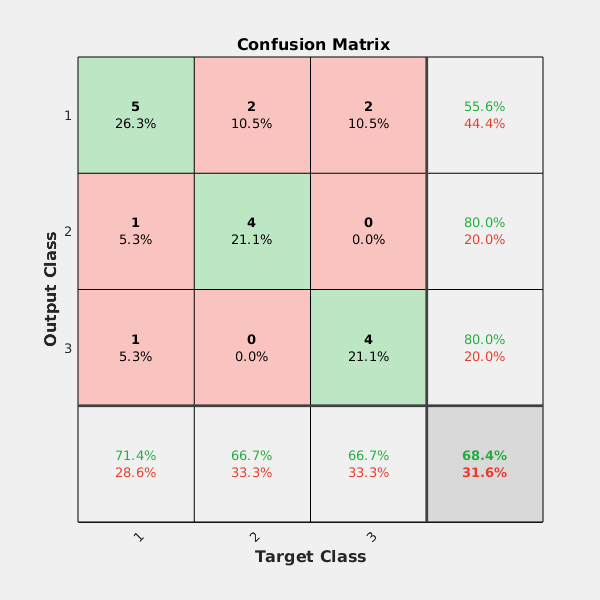

y = stackednet(dataTest_T);
plotconfusion(labelTest_T,y);

stackednet = train(stackednet,dataTrain_T,labelTrain_T);

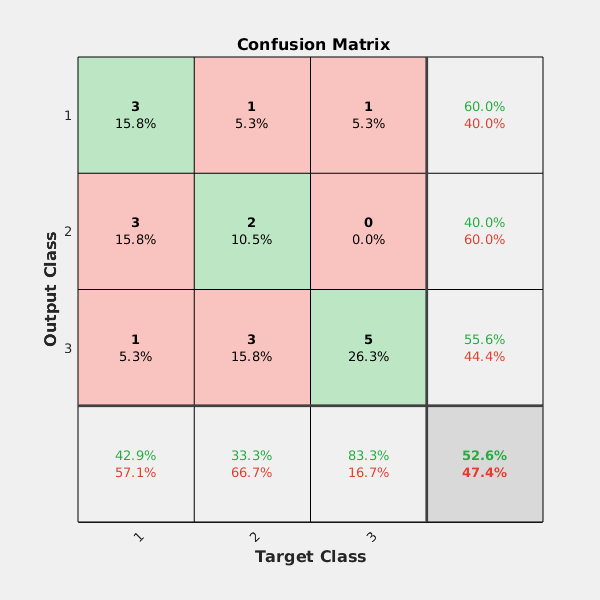

y = stackednet(dataTest_T);
plotconfusion(labelTest_T,y)

save


Saving to: /home/titan7/Vidhi/ArrayCGH/Autoencoder_7aug2019/matlab.mat



## Train Softmax layer on feat4 obtained from autoencoder

rng(1);
softnet = trainSoftmaxLayer(feat4,labelTrain_T,'MaxEpochs',400);

## Stacked Autoencoder-softmax layer

stackedautoenc_softmax = stack(autoenc1,autoenc2,autoenc3,autoenc4,softnet);
view(stackedautoenc_softmax)

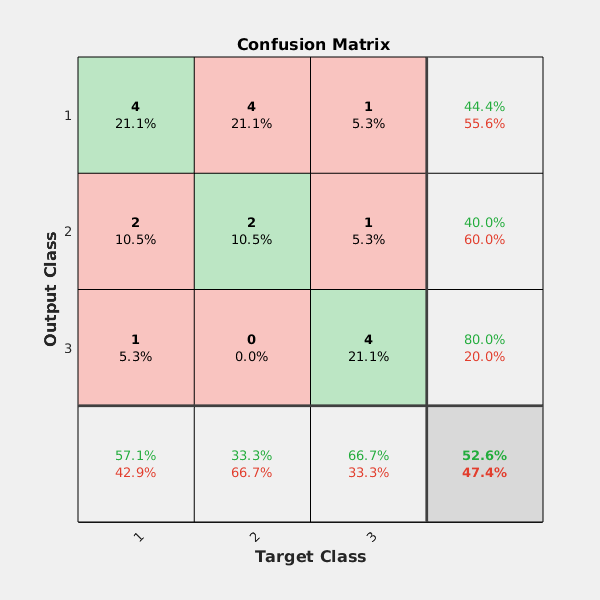

y_softnet = stackedautoenc_softmax(dataTest_T);
plotconfusion(labelTest_T,y_softnet)

stackedautoenc_softmax = train(stackedautoenc_softmax,dataTrain_T,labelTrain_T);

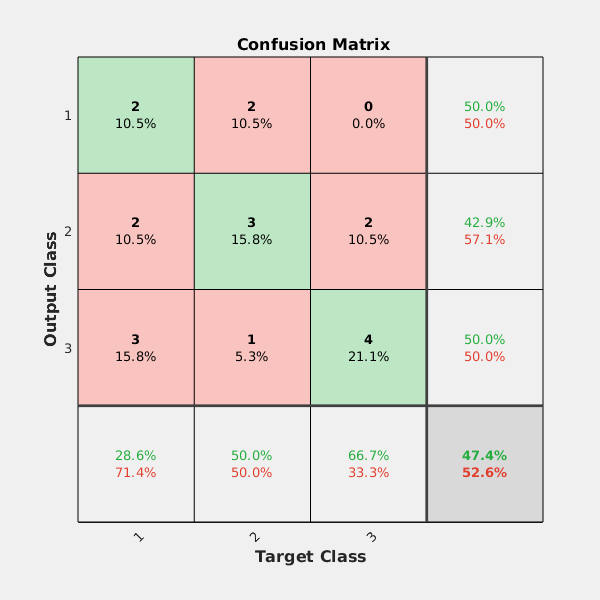

y_softnet = stackedautoenc_softmax(dataTest_T);
plotconfusion(labelTest_T,y_softnet)

%save

% Feature Ranking

 SVM_Input=table(feat4,dataTest_feat4);
 svmInput=(table2array(SVM_Input))';
 SVM_Input=table(svmInput);
 SVM_Input.class= response;
 feature_table1 = SVM_Input;
%T = newData.class;
rng(1)
% Use 70% of data for training and remaining for testing
split_training_testing = cvpartition(SVM_Input.class, 'Holdout', 0.3);
% Dummyvar
SVM_Input.class = dummyvar(SVM_Input.class);
% Create a training set
training_set = feature_table1(split_training_testing.training, :);

% Create a validation set
testing_set = feature_table1(split_training_testing.test, :);

grpstats_training = grpstats(training_set, 'class', 'mean');
disp(grpstats_training(:,'GroupCount'))

          GroupCount
          __________

    0         22    
    10        19    
    11        27    




% Create a random sub sample (to speed up training) from the training set
subsample = [1:height(training_set)];

% Create a 10-fold cross-validation set from training data
cvp = cvpartition(length(subsample),'KFold',10);

% Perform feature selection with neighborhood component feature selection
rng(1)
mdl = fscnca(table2array(training_set(:,1:(length(feature_table1.Properties.VariableNames)-1))), ...
    table2array(training_set(:,length(feature_table1.Properties.VariableNames))), 'Lambda', 0.005, 'Verbose', 0);

% Select features with weight above 1
selected_feature_indx = find(mdl.FeatureWeights > 0.01);

% Plot feature weights
stem(mdl.FeatureWeights,'bo');


% Load saved array of selected feature indexes to ensure reproducibility
%load('SelectedFeatures.mat')

% Display list of selected features
cnv_sel_features_weight=mdl.FeatureWeights(selected_feature_indx)

cnv_sel_features_weight =     1.6960
    1.7013


cnv_features_weight=mdl.FeatureWeights

cnv_features_weight =     0.0677
    0.0808
    0.0869
    0.0801
    0.0521
    0.3355
    0.0051
    0.0790
    0.1234
    0.0898


final_table = svmInput(:,selected_feature_indx);
final_tableOut=table(final_table);
writetable( final_tableOut,'./autoencoder-nca_sel_features.xlsx', 'WriteRowNames',true);


X=svmInput;
%X=svmInput;
Y = response;
classOrder = unique(Y);
rng(1); 
classOrder()

ans = 3×1 categorical array
     0 
     10 
     11 


t = templateSVM('Standardize',true)

t = Fit template for classification SVM.

                     Alpha: [0×1 double]
             BoxConstraint: []
                 CacheSize: []
             CachingMethod: ''
                ClipAlphas: []
    DeltaGradientTolerance: []
                   Epsilon: []
              GapTolerance: []
              KKTTolerance: []
            IterationLimit: []
            KernelFunction: ''
               KernelScale: []
              KernelOffset: []
     KernelPolynomialOrder: []
                  NumPrint: []
                        Nu: []
           OutlierFraction: []
          RemoveDuplicates: []
           ShrinkagePeriod: []
                    Solver: ''
           StandardizeData: 1
        SaveSupportVectors: []
            VerbosityLevel: []
                   Version: 2
                    Method: 'SVM'
                      Type: 'classification'


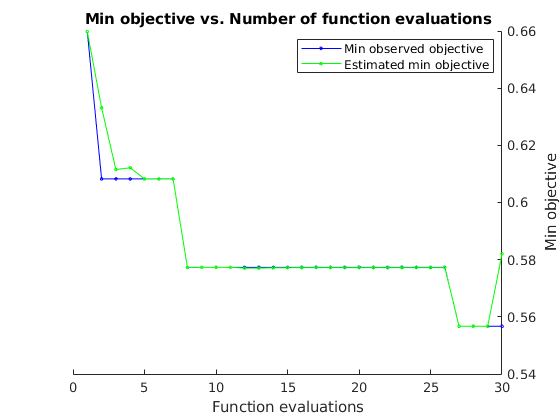

|=================================================================================================================================================================|
| Iter | Eval   | Objective   | Objective   | BestSoFar   | BestSoFar   |       Coding | BoxConstraint|  KernelScale | KernelFuncti-| PolynomialOr-|  Standardize |
|      | result |             | runtime     | (observed)  | (estim.)    |              |              |              | on           | der          |              |
|=================================================================================================================================================================|
|    1 | Best   |     0.65979 |     0.12571 |     0.65979 |     0.65979 |     onevsall |     0.091111 |            - |       linear |            - |        false |
|    2 | Best   |     0.60825 |     0.11986 |     0.60825 |     0.63315 |     onevsone |    0.0018751 |            - |       linear |            - |         true |
|    3 | Accept 

%% Train a classifier
% This code specifies all the classifier options and trains the classifier.
opts= struct('Optimizer', 'bayesopt', 'ShowPlots',true, 'AcquisitionFunctionName', 'expected-improvement-plus' );
Mdl = fitcecoc(...
    X, ...
    Y, 'Learners',t,...
    'Optimizehyperparameters', 'all',...
    'HyperparameterOptimizationOptions',opts,...
    'ClassNames', classOrder);

%CVSVMModel = crossval(Mdl)
%% Create the result struct with predict function

rng (1);
predictorExtractionFcn = @(x) array2table(x, 'VariableNames', predictorNames);
svmPredictFcn = @(x) predict(Mdl, x);
trainedClassifier.predictFcn = @(x) svmPredictFcn(predictorExtractionFcn(x));

% Add additional fields to the result struct
trainedClassifier.ClassificationSVM = Mdl;
trainedClassifier.About = 'This struct is a trained model exported from Classification Learner R2019a.';
trainedClassifier.HowToPredict = sprintf('To make predictions on a new predictor column matrix, X, use: \n  yfit = c.predictFcn(X) \nreplacing ''c'' with the name of the variable that is this struct, e.g. ''trainedModel''. \n \nX must contain exactly 373 columns because this model was trained using 373 predictors. \nX must contain only predictor columns in exactly the same order and format as your training \ndata. Do not include the response column or any columns you did not import into the app. \n \nFor more information, see How to predict using an exported model.');

% Extract predictors and response
% Perform cross-validation
partitionedModel = crossval(Mdl, 'KFold', 10);

% Compute validation predictions
[validationPredictions, validationScores] = kfoldPredict(partitionedModel);

% Compute validation accuracy
validationAccuracy = 1 - kfoldLoss(partitionedModel, 'LossFun', 'ClassifError');
validationAccuracy

validationAccuracy = 0.4124

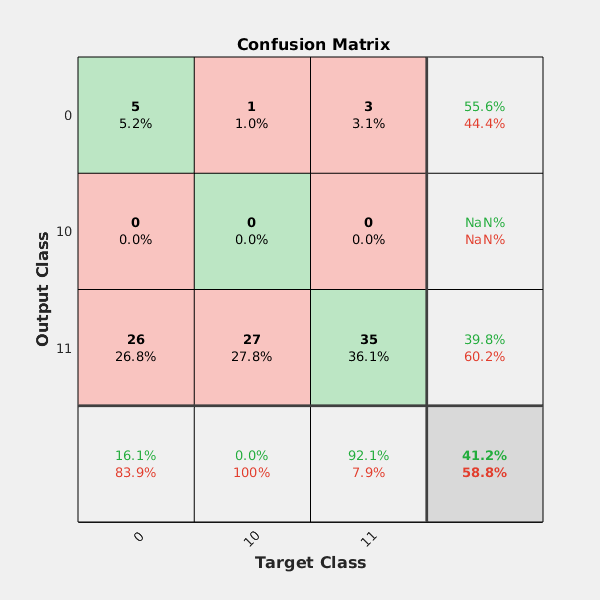

plotconfusion(Y, validationPredictions)

X = svmInput;
Y = response;
classOrder = unique(Y);
rng (1); % For reproducibility
classOrder();

%% Train a classifier
% This code specifies all the classifier options and trains the classifier.

t = templateTree('MaxNumSplits', 20);
enMdl = fitcensemble(X,Y,'Method', 'RUSBoost', 'Learners',t, ...
    'HyperparameterOptimizationOptions',struct('AcquisitionFunctionName','expected-improvement-plus'));

%% crossval
crossv = crossval(enMdl, 'KFold', 10);
[ensValidationPredictions, ensValidationScores] = kfoldPredict(crossv);

%% loss
ensValidationAccuracy = 1 - kfoldLoss(crossv, 'LossFun', 'ClassifError');      
ensValidationAccuracy()

ans = 0.3299

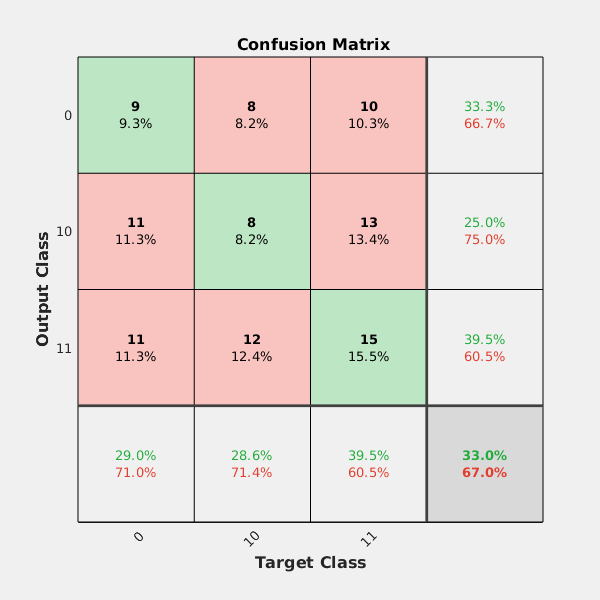

plotconfusion(Y, ensValidationPredictions)